#  循环码分析

本篇文章按照的如下逻辑组织。首先分析循环码，然后分析循环码的特例-BCH码，然后经分析BCH码的特例RS码。

## 1.  循环码

### 1.1 循环码原理

    循环码是线性分组码的一种，具有循环性。就是码组中的任何一个码字经过左右移位会成为码组中的另外一个码字。

    以书上给出的（7,3）循环码为例，码字$a_6 a_5 a_4 a_3 a_2 a_1 a_0$，前三位$a_6 a_5 a_4$为信息位，后四位$a_4 a_3 a_2 a_1 a_0$为监督位。

    码多项式$T\left(x\right)=a_6 x^6 +a_5 x^5 +a_4 x^4 +a_3 x^3 +a_2 x^2 +a_1 x^1 +a_0$

    有一个定理：在循环码中，如果$T\left(x\right)$是一个许用码组，那么${\mathrm{x}}^i \cdot T\left(x\right)$在模$x^n +1$的运算下，也是该编码中的一个许用码组。也就是说，一个长为n的循环码，一定是按照模$x^n +1$运算的一个余式。

    循环码中，一个（n,k）码有$2^k$个不同的码组。若用g(x)表示前k-1位皆是0的码组，那么$g\left(x\right),\mathrm{xg}\left(x\right),\ldotp \ldotp \ldotp ,x^{k-1} g\left(x\right)$,都是码组，且是线性无关的，所以可以用这样的一组码字来构成循环码的生成矩阵G。g(x)必须是一个常数项不为零的（n-k）次多项式，而且这个g(x)还是这种(n,k)码中次数为（n-k）的唯一一个多项式，称为码的生成多项式。

    所有的码多项式$T\left(x\right)$都能够被$g\left(x\right)$整除，而且任何一个次数不大于k-1的多项式乘以$g\left(x\right)$都是码多项式。

    如何寻找任一（n,k）循环码的生成多项式？结论：生成多项式$g\left(x\right)$应该是$x^n +1$的一个因子。也就是说循环码的生成多项式应该是$x^n +1$的一个（n-k）次因式。

截短循环码。正常循环码的基础上，只选取信息前i比特为零的码字，构成（n-i,k-i）截短循环码，可以提高码率。

### 1.2 循环码编码

    约定n，k和生成多项式。

n=7; %码长
k=3; %信息长
gx = [1 0 1 1 1]; %生成多项式
%cyclpoly(7,3,'all') %matlab自带函数，可以寻找n,k对应的生成多项式

生成生成多项式G的方式多种。

生成多项式向左移位。

G1 = zeros(k,n);
for i = 1:k
    G1(k+1-i,k-i+1:n-i+1) = gx;
end
%化为行最简形
G = transSimplestRowsGF2V3(G1)

G =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


编码也就是信息码字乘以生成矩阵即可；

### 1.3 循环码解码

    可以采用捕错解码，和之前介绍的线性分组码一致。

### 1.4 循环码逆向分析

    逆向分析的思路的也和线性分组码一致。只是作为线性分组码的特例，如果知道的码长，那么生成矩阵G也就大概确定了，尝试几次即可。

## 2.  BCH码

### 2.1 BCH原理

    BCH码时一种能够纠正多个错码的循环码。BCH解决了生成多项式与纠错能力的关系问题，可以在给定纠错能力要求的条件下，寻找到码的生成多项式。

    本原BCH码：$g\left(x\right)$是本元多项式；$g\left(x\right)$的最高次为m,码长满足$n=2^m -1;m\ge 3$

    非本原BCH码：$g\left(x\right)$中不包含本元多项式，且码长n一定除得尽$2^m -1$

    扩展BCH码：在BCH码的生成多项式中乘上一个因式（x+1）；BCH码长度都是奇数，为了得到偶数长度的码，并且增大检错能力；扩展BCH码不再具有循环性。

q进制BCH码：设q进制循环码的生成多项式为g(x)，包含有2t=r个连续根，即，则由g(x)生成的（n，k）循环码称为q进制BCH码。

  BCH码的最小码距d = 2t十1，能够纠正t个错误，纠正单个错误的BCH码就是循环Hamming码。由于BCH码为循环码的一个特殊类型，其编码完全可以按循环码的编码方式进行，只要选择合适的码长和生成多项式即可。

### 2.2 BCH编解码  

BCH码时循环码的一种，编解码同样可以依据循环码的原理。下面以（7,4）BCH码为例说明。

%(7,4)BCH码
n = 7;%码长
k = 4;%信息组长度
codewordsnum = 1000;%BCH码字数目
[genpoly,t] = bchgenpoly(n,k);%生成多项式和纠错能力
msg = randi([0 1],codewordsnum,k); %信息每行一个bch
Gmsg = gf(msg);%转到Galois域
bchscodewords = bchenc(Gmsg,n,k);%可以从编码后的码字中清晰的看出循环码的特征
sbits = reshape(bchscodewords',1,codewordsnum*n);

进过信道传输，会有的误码且码字起始比特未知。

errorrate = 1e-2;%误码率
rbits = sbits + gf(randerr(1,length(sbits),errorrate*length(sbits)));%加上误码
rbits_startunknown = rbits(randi([1 n]):end);%随机起始位置

### 2.3 基于码根的容错分析法

这个方法的前提条件是 码字起始位置已知。

通过公共码根的比例，构造一个统计量P。按照P值的大小确定码长。

%假设一个起始位置
startbit = 1;%码流首比特在码字中的位置
errorrate = 0.01;%误码率
rbits = sbits + gf(randerr(1,length(sbits),errorrate*length(sbits)));%加上误码
rbits_startunknown = rbits(startbit:end);%随机起始位置

%猜测m，形成生成多项式
m = 3;
A = gf(2,m);
pl = minpol(A);
%检测码长，从3到30
P = zeros(1,25);
for n1 = 3:20
    rcodewordsnum = floor(length(rbits_startunknown)./n1);
    rcodewords = reshape(rbits_startunknown(1:rcodewordsnum*n1),n1,rcodewordsnum);
    rcodewords = rcodewords';
    %对每一个码字求码根
    codewordroots = zeros(rcodewordsnum,n1);
    for i = 1:rcodewordsnum %遍历所有的接收码字
        rcw = rcodewords(i,:);
        % 首先判断rcw是是否为全零码字
        if ~any(rcw)
            codewordroots(i,1:n1) = 0;
            continue;
        end
        
        %判断α^0是否是一个根
        if rcw*gf(ones(n1,1))==0
            codewordroots(i,1) = 1;
        end
        
        for ai = 1:n1-1 %依次代入α^1,α^3...α^6
            %确定存储乘法结果的最高次，构造向量
            resai = gf(zeros(1,findHightestRankofCodeWord(rcw)*ai+1));
            %代入α^ai，到码字多项式.遍历码字
            for ci = 1:n1
                if rcw(ci) == 1
                   resai(length(resai)-(n1-ci)*ai) = 1;            
                end        
            end % ci
            %进行GF2上的多项式除法
            %[d3, r3] = deconv(resai,rcw(n1-findHightestRankofCodeWord(rcw):end));
            [d3, r3] = deconv(resai,pl);
            
            if ~any(r3) %如果所有的都是0，则执行。此时表明ai是一个根
                codewordroots(i,ai+1) = 1;
            end
        end % ai   
    end % end i
    
    ti = sum(codewordroots)./rcodewordsnum;
    tv = sum(sum(codewordroots)./rcodewordsnum);
    yita = sum(((ti-tv/n1).^2)*n1/tv)
    %根据书上的P值无法得到书上示例的那样大小显著变化的P，但是正确码长的yita值与不正确码长有很大的差异。
    %P(n1) = 1-igamma(n1/2,yita/2)/gamma(n1/2)
    %1-gammainc(n1/2,yita/2)
end

yita = 0.7432

yita = 0.6747

yita = 0.5030

yita = 0.4745

yita = 2.1068

yita = 0.7911

yita = 1.0741

yita = 1.0859

yita = 1.4100

yita = 0.7234

yita = 0.7730

yita = 3.2421

yita = 1.0388

yita = 3.2564

%确定码长后，确定优势码根
n1 = 7;
rcodewordsnum = floor(length(rbits_startunknown)./n1);
rcodewords = reshape(rbits_startunknown(1:rcodewordsnum*n1),n1,rcodewordsnum);
rcodewords = rcodewords';
%对每一个码字求码根
codewordroots = zeros(rcodewordsnum,n1);
for i = 1:rcodewordsnum %遍历所有的接收码字
    rcw = rcodewords(i,:);
    % 首先判断rcw是是否为全零码字
    if ~any(rcw)
        codewordroots(i,1:n1) = 0;
        continue;
    end
    
    %判断α^0是否是一个根
    if rcw*gf(ones(n1,1))==0
        codewordroots(i,1) = 1;
    end
    
    for ai = 1:n1-1 %依次代入α^1,α^3...α^6
        %确定存储乘法结果的最高次，构造向量
        resai = gf(zeros(1,findHightestRankofCodeWord(rcw)*ai+1));
        %代入α^ai，到码字多项式.遍历码字
        for ci = 1:n1
            if rcw(ci) == 1
               resai(length(resai)-(n1-ci)*ai) = 1;            
            end        
        end % ci
        %进行GF2上的多项式除法
        %[d3, r3] = deconv(resai,rcw(n1-findHightestRankofCodeWord(rcw):end));
        [d3, r3] = deconv(resai,pl);
        
        if ~any(r3) %如果所有的都是0，则执行。此时表明ai是一个根
            codewordroots(i,ai+1) = 1;
        end
    end % ai   
end % end i
ti = sum(codewordroots)./rcodewordsnum

ti =     0.4470    0.8720    0.8720    0.0640    0.8720    0.0640    0.0640


经过分析码根为$\alpha^1 \;\;\alpha^2 \;\;\alpha^4 \;\;$

构造$\mathrm{GF}\left(2^3 \right)$的元素对照表如下，多项式为$1011-D^3 +D^1 +D^0$


$$\left\lbrack \begin{array}{ccccc}
\alpha^0  & 0\;0\;1 & | & \alpha^4  & 1\;1\;0\\
\alpha^1  & 0\;1\;0 & | & \alpha^5  & 1\;1\;1\\
\alpha^2  & 1\;0\;0 & | & \alpha^6  & 1\;0\;1\\
\alpha^3  & 0\;1\;1 & | & \alpha^7  & 0\;0\;1
\end{array}\right\rbrack$$


然后构造H矩阵如下：


$$\left\lbrack \begin{array}{ccccccc}
{\left(\alpha^1 \right)}^6  & {\left(\alpha^1 \right)}^5  & {\left(\alpha^1 \right)}^4  & {\left(\alpha^1 \right)}^3  & {\left(\alpha^1 \right)}^2  & {\left(\alpha^1 \right)}^1  & {\left(\alpha^1 \right)}^0 \\
{\left(\alpha^2 \right)}^6  & {\left(\alpha^2 \right)}^5  & {\left(\alpha^2 \right)}^4  & {\left(\alpha^2 \right)}^3  & {\left(\alpha^2 \right)}^2  & {\left(\alpha^2 \right)}^1  & {\left(\alpha^2 \right)}^0 \\
{\left(\alpha^4 \right)}^6  & {\left(\alpha^4 \right)}^5  & {\left(\alpha^4 \right)}^4  & {\left(\alpha^4 \right)}^3  & {\left(\alpha^4 \right)}^2  & {\left(\alpha^4 \right)}^1  & {\left(\alpha^4 \right)}^0 
\end{array}\right\rbrack$$


化简


$$\left\lbrack \begin{array}{ccccccc}
\alpha^6  & \alpha^5  & \alpha^4  & \alpha^3  & \alpha^2  & \alpha^1  & 1\\
\alpha^{12}  & \alpha^{10}  & \alpha^8  & \alpha^6  & \alpha^4  & \alpha^2  & 1\\
\alpha^{24}  & \alpha^{20}  & \alpha^{16}  & \alpha^{12}  & \alpha^8  & \alpha^4  & 1
\end{array}\right\rbrack$$


再化简 


$$\left\lbrack \begin{array}{ccccccc}
\alpha^6  & \alpha^5  & \alpha^4  & \alpha^3  & \alpha^2  & \alpha^1  & 1\\
\alpha^5  & \alpha^3  & \alpha^1  & \alpha^6  & \alpha^4  & \alpha^2  & 1\\
\alpha^3  & \alpha^6  & \alpha^2  & \alpha^5  & \alpha^1  & \alpha^4  & 1
\end{array}\right\rbrack$$


构造H

H1=[1 1 1 0 1 0 0;
    0 1 1 1 0 1 0;
    1 1 0 1 0 0 1;
    1 0 0 1 1 1 0;
    1 1 1 0 1 0 0;
    1 1 0 1 0 0 1;
    0 1 1 1 0 1 0;
    1 0 0 1 1 1 0;
    1 1 0 1 0 0 1];
transSimplestRowsGF2V3(H1)%化为行最简，即可得到校验矩阵。

ans =      1     0     0     1     1     1     0
     0     1     0     0     1     1     1
     0     0     1     1     1     0     1
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


化为行最简后，前面3行就是所求的H校验矩阵。

### 2.4 基于求解公因式的容错分析法

%(7,4)BCH码
n = 7;%码长
k = 4;%信息组长度
num = 100;%BCH数目
errt = 0.01;
[genpoly,t] = bchgenpoly(n,k);%生成多项式和纠错能力
msg = randi([0 1],num,k); %信息每行一个bch
%msg = [0 1 0 1];
Gmsg = gf(msg);%转到Galois域
c1 = bchenc(Gmsg,n,k);
c2 = reshape(c1',1,num*n);


`为了模拟实际信道，我按照误码率加入噪声（误码率`1/1000`），并且模拟了接收到的比特流的第一比特并不总是码字的第一比特。代码如下所示。`

c2 = c2 + randerr(1,num*n,num*n*errt);
c2 = c2(randi([1 n]):end);%接收码子起始比特随机

BCH`码分析需要识别的未知参数是：码长，信息位长，码字起点和生成多项式。`

`而确定码子起点和码长又是求解码长和生成多项式的基础。故我首先求解码长和码字起点。``首先确定`BCH`所在的`GF(2m)`的`m`值，这个值可以试着来取，按照从小到大的顺序，如下图所示`

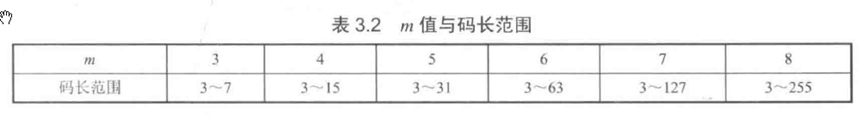

`确定`m`后，在上表中码长范围内进行遍历，并且遍历码字起点；当遍历到某一码长和起点时，会得到`N`个待定码组，`N`可以按照需要自选。如果`N`值选的大的话，后面求解公因式比较慢，但是准确度较高。`

`我采用了辗转相除算法递归计算两个`GF(2)`多项式的最大公因式，函数为自编的gf2vecgcd(s1,s2)。`

`利用待定码组进行计算。首先两两计算公因式，如果某一个码组与别的码组的公因式的阶数小于`m`的情况比较多（程序中利用`p1`参数进行调节），那么该码字将作为错误码子被剔除。如果被剔除的码组过多（程序中利用`p2`参数进行调节），则待定码组码长和起点的组合不正确，需要继续进行遍历。`

N=20;%分析的码字数
save = 0;%保留的码字
p1 = 0.8;%噪声，剔除码字
p2 = 0.8;%判断码长是否正确
m = 3;
for ml = 3 : 2^m%ml为码长
    for start = 1:ml
        %取N个码子
        c3 = c2(start:start+N*ml-1);
        c4 = reshape(c3,ml,N);
        c5 = c4';
        save = 0;
        %两两算码子的公因式
        for n1 = 1:N
            count = 0;
            for n2 = 1:N
                ggcf = gf2vecgcd(c5(n1,:),c5(n2,:));
                if(length(ggcf)>=m)
                    count = count+1;
                end
            end
            if count/N > p1 %判断阶数的,可剔除误码
                save = save + 1;
                %保存正确码组
            end
        end
        if save/N>p2 %判断保留数目
            ml
            start
        end       
    end % start  
end % ml


`经过不断向上调整`N,p1,p2`参数的值，最终将只剩下一种码长起点类型。至此，已经可以确定码长为`7`，起点为`5。

`确定了码长和起点后，接下来确定生成多项式，实质就是求码子的最大公因式。这里为了避免噪声引入的误码，我对接收码子进行了预处理，即每个码子都与其他码子计算最大公因式。如果某码字和其他码字计算得到的最大公因式次数小于`m`或者相比其他码字普遍小，那么久把该码字提出，不参与接下来生成多项式的计算。`

ml = 7;
start = 5;
c3 = c2(start:start+N*ml-1);
c4 = reshape(c3,ml,N);
c5 = c4';
save = 0;
sc = gf(zeros(N,ml));
%两两算码子的公因式
for n1 = 1:N
    count = 0;
    for n2 = 1:N
        ggcf = gf2vecgcd(c5(n1,:),c5(n2,:));
        if(length(ggcf)>=m)
            count = count+1;
        end
    end
    if count/N > 0.8 %判断阶数的,可剔除误码
        save = save + 1;
        %保存正确码组
        sc(save,:) = c5(n1,:);
    end
end

%剔除误码码字得到sc，求公因式
gg = sc(1,:);
for ii = 2:save
    gg = gf2vecgcd(gg,sc(ii,:))    
end

`与生成`BCH`码时的生成多项式对比，发现正是所求，至此生成多项式【`1011`】和信息长度【`4`】均已确定，下一步可以按照分析出来的参数进行译码`

### `2.5 改进的线性矩阵分析法`

`基本思想：传统的矩阵分析法通过解方程分析BCH码参数需要大段连续无误码的高质量比特流数据，在解方程的方法不变的情况下，如果能够降低分析需要的数据量，则传统方法的容误码分析能力自然增强。`

`抽取拼接，多次验证，积小解为全解。`

`这里假设已经经历过了分析码长，起点，信息位的位置这些阶段。采用（7，4）BCH码，信息位在前四位，校验位在后三位。`

rcodewords = bchscodewords;
for i=1:3
    rw1 = rcodewords(:,[1 2 3 4 i+4]);
    rw1simple = transSimplestRowsGF2V4(rw1);
    rw1simple(1:5,:)
end

 
ans = GF(2) array. 
 
Array elements = 
 
   1   0   0   0   1
   0   1   0   0   1
   0   0   1   0   1
   0   0   0   1   0
   0   0   0   0   0

 
ans = GF(2) array. 
 
Array elements = 
 
   1   0   0   0   0
   0   1   0   0   1
   0   0   1   0   1
   0   0   0   1   1
   0   0   0   0   0

 
ans = GF(2) array. 
 
Array elements = 
 
   1   0   0   0   1
   0   1   0   0   1
   0   0   1   0   0
   0   0   0   1   1
   0   0   0   0   0



transSimplestRowsGF2V4(rcodewords)

 
ans = GF(2) array. 
 
Array elements = 
 
   1   0   0   0   1   0   1
   0   1   0   0   1   1   1
   0   0   1   0   1   1   0
   0   0   0   1   0   1   1
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0
   0   0   0   0   0   0   0

`对结果进行拼接，可以得到正确的生成矩阵。完毕。`

`一个困扰：通观察(7,4)BCH码的码字，产生一个困扰，发现所有的码字是不具有循环性的，这从生产矩阵里面也可以看出来。书上说对循环码的定义是，任何一个码字，经过循环后，还是该码的一个码字。从这个定义来说，是不要求所有的码都具备循环性的。用(7,4)BCH码举例，如果要求所有的码字都具备循环性，那么最多循环7-1=6次，就是加上全零码字，最多包含7个码子，但是信息位有4位，要求有16个不同的码字。退一步讲，就是全零码字，也是不符合所有码字都具备循环性这一个限制条件的，这应该是我想错了。`

## Last:用到的一些函数

function [gys] = gf2vecgcd(s1,s2)
%   s1次数大于s2的次数
%   求GF(2)上两个多项式的公因式，用辗转相除法
%   如果s2全零，s1即为所求
if any(s2,'all')==false
    %disp('s2全零');
    gys = s1;
    return;
else
    %去掉头上的非零
    for i = 1:length(s1)
        if s1(i)==1
            break;
        end
    end
    s1 = s1(i:end);
    for j = 1:length(s2)
        if s2(j)==1
            break;
        end
    end
    s2 = s2(j:end);
    [tmp, s3] = deconv(s1,s2);
    gys = gf2vecgcd(s2,s3);
end
end

function p = findHightestRankofCodeWord(bchcodeword)
    % 确定一个BCH码字的最高阶
    % bchcodeword:GF2的BCH码字、
    % 最高幂次数
    p = 0;
    for i = 1:length(bchcodeword)
        if bchcodeword(i)==1
            p = length(bchcodeword)-i;
            break;
        end
    end  % end i
end

function row = findKNonLinearRelevantCoedwords(rcode,k)
    %寻找k个线性不相关的码字，GF2上。
    % 这个函数优点问题，而且没哟考虑有限域，目前没有用，之后再修改。
    %codewords:码字矩阵，要求长度大于k
    %n:码长
    %首先找到k个线性不相关的接收码字
    [r1,c1] = size(rcode);
    row = [];
    r2 = 0;
    for i = 1 : r1
        row1 = [row;rcode(i,:)];
        if(rank(row1) > r2)
            row = row1;
            r2 = r2 +1;
        end
        
        if r2 >= k
            break;
        end
    end
end

function D = calcD(rbits,n1)
    % rbits为接收码流
    % n1为猜测的码长
    %根据猜测的码长构造接收码字
    rcodewordsnum = floor(length(rbits)./n1);
    rcodewords = reshape(rbits(1:rcodewordsnum*n1),n1,rcodewordsnum);
    rcodewords = rcodewords';%每行一个码字
    
    %计算每个码字的重量
    wordweight = sum(rcodewords,2);
    wordweightDistribute = zeros(1,n1+1);
    for i = 0:n1
        wordweightDistribute(i+1) = sum(wordweight==i);
    end
    Prbi = wordweightDistribute./rcodewordsnum;
    D = ((n1+1)./n1).*sum((Prbi-1/(n1+1)).*(Prbi-1/(n1+1)));
end



function codewords = transSimplestRowsGF2(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = i:m
            if codewords(j,i)==1
                i1 = j;
                break;
            end
        end % end j
        if i1==0 %没找到
            %disp('over');
            break;
        end
        %找到了，和第i行交换顺序
        temp = codewords(i,:);
        codewords(i,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=i
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(i,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func

%这个GF2上化为行最简，较上个版本的改进是考虑了当矩阵的秩小于码长时候，剩下部分的行变换。
function codewords = transSimplestRowsGF2V2(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;
                cl = cl+1;
                break;
            end
        end % end j
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(cl,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func

%这个GF2上化为行最简，较上个版本的改进是考虑了当矩阵的秩小于码长时候，剩下部分的行变换。
function codewords = transSimplestRowsGF2V3(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;                
                break;
            end
        end % end j
        cl = cl+1;
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(cl,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func


function codewords = transSimplestRowsGF2V4(codewords)
    % 在GF2上把codewords化为行最简形,输入为GF(2)
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;                
                break;
            end
        end % end j
        cl = cl+1;
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = codewords(i2,:) + codewords(cl,:);
                end
            end
        end %end i2   
    end  %end i    
end %end func

